# Class: Wireless Communications, Prof. Sundeep Ragan

# Student: Jaime Lima, jdl679, N17822573 

# Project: A Short Qualitative and Quantitative Investigation on NR Phase Noise Modeling, ICI and CPE 

## **Abstract **

In this project we will do some simple experiments to understand the effect of **phase noise** in OFDM systems and use of the phase tracking reference signals (PT-RS) to mitgate the impact of phase noise in a simulated 5G OFDM system. We will provide a visual a qualitivative observation of Intercarrier interference (ICI) and use the MATLAB 5G tools to do a more quantiative correction of the the common phase error (CPE). We will measure the error vector magnitude (EVM) and bit error rate (BER) with and without CPE compensation for **an ideal channel and also for a fading channel with AGWN similar to the one we used in Lab4.** We will also present a visual indication of how the energy of the PT-RS amd DM-RS signals disperse due to the phase noise and show the phase noise magnitude response curves of different  3GPP phase noise models. In this exercise we expanded the scope of the example provided in ref (2) in a significant way.

In 5G NR, 3GPP introduces a new reference signal, named phase tracking reference signal (PT-RS), to deal with oscillator noise (2). The noise incurred in the TX and RX oscillators results in phase and in less extent amplitude modulation of the information signal, leading to significant changes in the frequency spectrum and timing properties of the information signal (1,2,3,4,5) . This phenomenon related to oscillators is called phase noise and it is explained and simulated extensively in (2,3).

Phase noise produced in local oscillators introduces a significant degradation at millimeter wave (mmWave) frequencies, depending on the power spectral density of phase noise (2). Phase noise leads to CPE and intercarrier interference (ICI). CPE leads to an identical rotation of a received symbol in each subcarrier. ICI leads to a loss of orthogonality between the subcarriers. 

**RESULTS**: the use of of the PT-RS togetther with DM-RS allowed for the proper equalization of both the ideal and the AGWN channels in the simulation. Evidence of ICI was displayed but no tentative to mitigate it was included in this present work. To simplify the project only one phase noise (model B) was used. Other phase noise and channel models can be easily added to the code in order to extend the current work.

## **1. Introduction **

A ideal oscillator generates a pure sine wave as we see in the math books, which would have a representation of a Dirac delta function in the frequency domain. However, in practice all oscillators have imperfections that make them to not generate a sinusoidal exactly. This makes the spectral line in the frequency domain to widen as shown in the picture below. The random variation in the phase of the wavefor is called phase noise. These variation have detrimental effect in communcation systems and they can up to some extent mitigated.

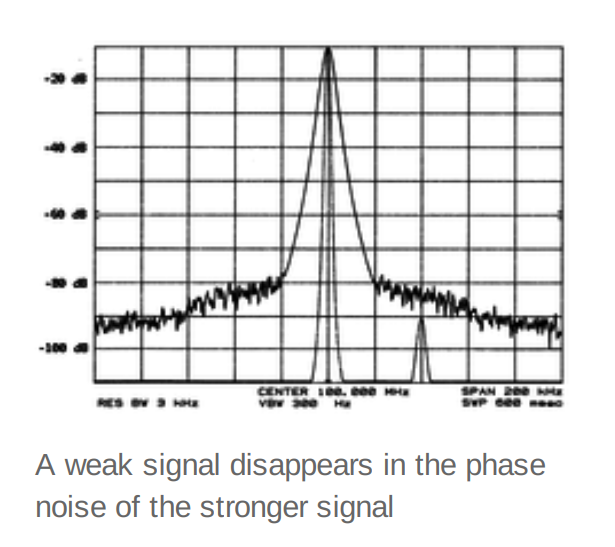

Source: Wikipedia. Note the smaller signal being masked by the frequency spread caused by the phase noise in the stronger one.

Phase noise causes energy to disperse in the frequency domain. This can have several effects in communiciation systems. In OFDM this can cause common phase rotations/errors (CPE) and loss of ortogonality among the subcarries, which causes energy to 'leak' from uma sub-carrier to the others causing inter-symbol interference in the frequency domain, known as intercarrier interference (ICI).

The picture below depicts a tipical OFDM system using in wiress. We will simulate this system with enphasis in the phase noise injection, using the excellent tools provided by MATLAB to facilitate the numerical implementation of system under study.

## 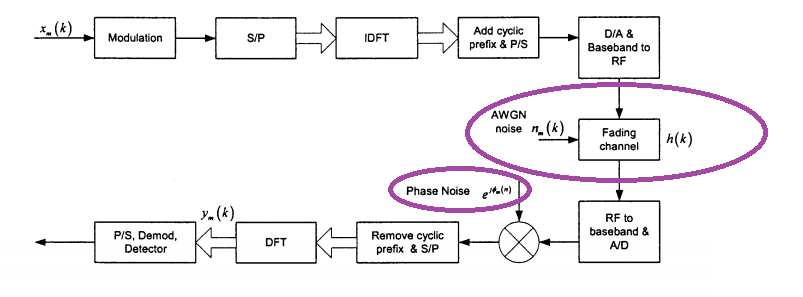

                                   Model of wireless system inclusing phase noise (picture taken from (1))

## **2. A Few Formulas **

To better appreciate the simulation, it is import to have in mind some formulas. At the transmitter side, an OFDM signal can be thought as m parallel **x_m(n)** discrete time series being transmitted, each one modulated in a separte sub-carrier that is placed in a very specific and delicate arrangement to make them orthogonal. The arrangement is done in frequency domain by creating each symbol sequence **s_m(k)** and taking a IDFT, as shown in (1):

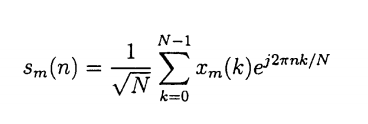

The result final spread spectrum signal signal to be transmitted  is obtained by adding all **m** contributions at the discrete time **n**. One important detail is that the **n** above starts from -N_g to (N-1). This is to create guard in the signal (namely the ciclical prefix) to combat time-domain inter-symbol interference (ISI). 

At the receiver side, in the presence of multipath effects and noise, the receiver signal can be written as (1):

where the convolution operator is the *circle with the x inside*, *F^-1(.) operator is the circular IDFT* and **n_m(n)** represents the gaussian nose. Also, **h(k)** is the channel response, which is in more generic terms is a convolution and usuall is assumed to be invariant with a block and not function of **m** (this requirement can be relexed if more training symbols are made avaible).

After removal of the cyclic prefix and execution of the DFT the received **kth** subcarrier of the **m-th **symbol can be expressed by the formula below (1), with the phase noise being taken into consideration:

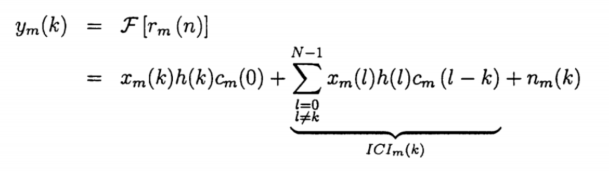

where **x_m(k) **is the data signal and** h(k) **is the channel complex gain and **n_m(k)** is the AWGN noise. The term **c_m()** is the common phase error. The summation in the second terms is zero when phase noise is not present because the orthogonal porperties of the **sinc()** function. When orthogonality is lost, the second terms represents the ICI, expressing the energy from a symbol transmiited in one subcarrier leaking into other subcarrier, leading to detection errors (1).

The term **c_m()** is given by:

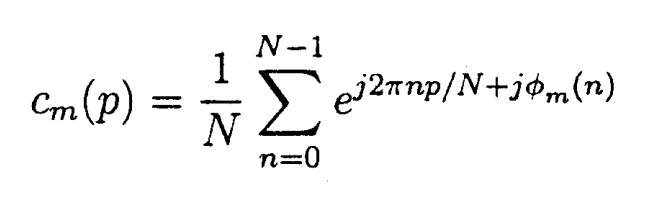

And it is exactly IDFT the phase noise random rotation factor ***exp(phi_m(n))***.

The phase noise is usually described as a continuos random Wiener process with zero mean, having as such Gaussian increments and power that monotonically increases over time (1).

*NOTE: the formulas above were taken from reference (1), where a detailed in-depth description of the what is mentioned above can be found.*

## **3. Block Diagram of the Simulation**

The diagram below is a modified version of the one found in (2) and shows the several blocks that we are presently simulating:

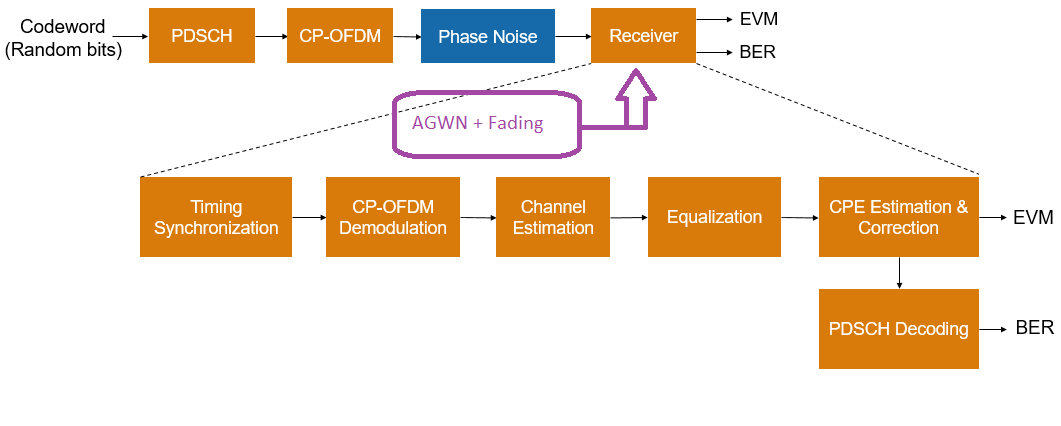

## **4. Phase Noise Modeling**

Below three different  phase noise model curves are shown. We will use the model 'B' for the rest of the present simulation

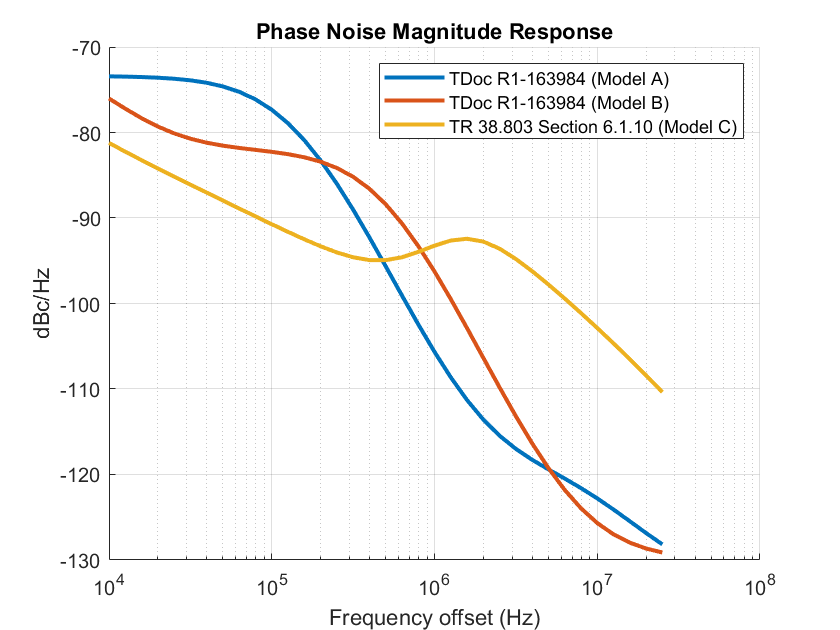

clear all

% Models 'A', 'B', or 'C': parameter sets 'A' and 'B' are obtained from practical 
% oscillators operating at 30 GHz and 60 GHz, respectively, as described in TDoc R1-163984. 
% The parameter set 'C' is obtained from the practical oscillator operating at 29.55 GHz, 
% as described in TR 38.803 Section 6.1.10.

% But First Configure carrier, as we need the params for the PN Modeling
carrier                   = nrCarrierConfig;
carrier.SubcarrierSpacing = 60; % KHz
carrier.CyclicPrefix      = 'normal';
carrier.NSizeGrid         = 66;

% Set the operating frequency and choose the phase noise model
simParameters         = [];
% simParameters.Fc      = 30e9;    % Frequency in Hz
% simParameters.PNModel = 'A';     % 'A' (TDoc R1-163984 Set A)
  simParameters.Fc      = 60e9;    % Frequency in Hz
  simParameters.PNModel = 'B';     % 'B' (TDoc R1-163984 Set B)
% simParameters.Fc      = 29.55e9; % Frequency in Hz
% simParameters.PNModel = 'C';     % 'C' (TR 38.803)

% Get the sample rate
waveformConfig = nrOFDMInfo(carrier);
sr             = waveformConfig.SampleRate;

% Phase noise level
foffsetLog = (4:0.1:log10(sr/2));    % Model offset from 1e4 Hz to sr/2 Hz
foffset    = 10.^foffsetLog;         % Linear frequency offset
pn_PSD     = PN_Model2Use(foffset,simParameters.Fc, simParameters.PNModel);  % dBc/Hz

% Set phase noise level
pnoise = comm.PhaseNoise('FrequencyOffset',foffset,'Level',pn_PSD,'SampleRate',sr);
pnoise.RandomStream = "mt19937ar with seed";

% Visualize spectrum mask of phase noise
pn_PSD_A = PN_Model2Use(foffset,simParameters.Fc, 'A');  % dBc/Hz
pn_PSD_B = PN_Model2Use(foffset,simParameters.Fc, 'B');  % dBc/Hz
pn_PSD_C = PN_Model2Use(foffset,simParameters.Fc, 'C');  % dBc/Hz
figure 
hold on
semilogx(foffset,pn_PSD_A, 'LineWidth',2);
semilogx(foffset,pn_PSD_B, 'LineWidth',2);
semilogx(foffset,pn_PSD_C, 'LineWidth',2);
set(gca,'xscale','log')
legend(["TDoc R1-163984 (Model A)", ...
        "TDoc R1-163984 (Model B)", ...
        "TR 38.803 Section 6.1.10 (Model C)"], "Location", "Northeast")
hold off
xlabel('Frequency offset (Hz)')
ylabel('dBc/Hz')
title('Phase Noise Magnitude Response')
grid on

*We will use the model B for the simulations below*.

## **5. Configuration PDSCH that will be used in the Simulation**

The example configures PDSCH occupying the complete carrier with modulation scheme set to '64QAM' and number of layers set to 1. The example defaults to a single layer and a single codeword of random uncoded bits.

% Set PDSCH parameters
pdsch = nrPDSCHConfig;
pdsch.PRBSet = 0:carrier.NSizeGrid-1;
pdsch.SymbolAllocation = [0 14];
pdsch.Modulation = '64QAM';
pdsch.NumLayers = 1;
pdsch.MappingType = 'A';
pdsch.NID = 1;
pdsch.RNTI = 2;

% Set DM-RS parameters
pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.DMRSTypeAPosition = 2;
pdsch.DMRS.DMRSAdditionalPosition = 0;
pdsch.DMRS.DMRSLength = 1;
pdsch.DMRS.DMRSPortSet = [];
pdsch.DMRS.NumCDMGroupsWithoutData = 1;
pdsch.DMRS.NIDNSCID = 1;
pdsch.DMRS.NSCID = 0;

% Set PT-RS parameters
pdsch.EnablePTRS = 1;
pdsch.PTRS.TimeDensity = 1;
pdsch.PTRS.FrequencyDensity = 2;
pdsch.PTRS.REOffset = '00';
pdsch.PTRS.PTRSPortSet = [];

## **6. Generation of the Waveform**

The waveform is generated for 2 frames and the field `NumFrames` of `simParameters` structure controls the number of frames of the waveform. The steps involved are:

- Generate random codeword with the bit capacity of PDSCH

- Get the PDSCH symbols for the random codeword and map them to grid

- Generate and map DM-RS symbols to grid

- Generate and map PT-RS symbols to grid

- Perform OFDM modulation for the complete grid of all frames

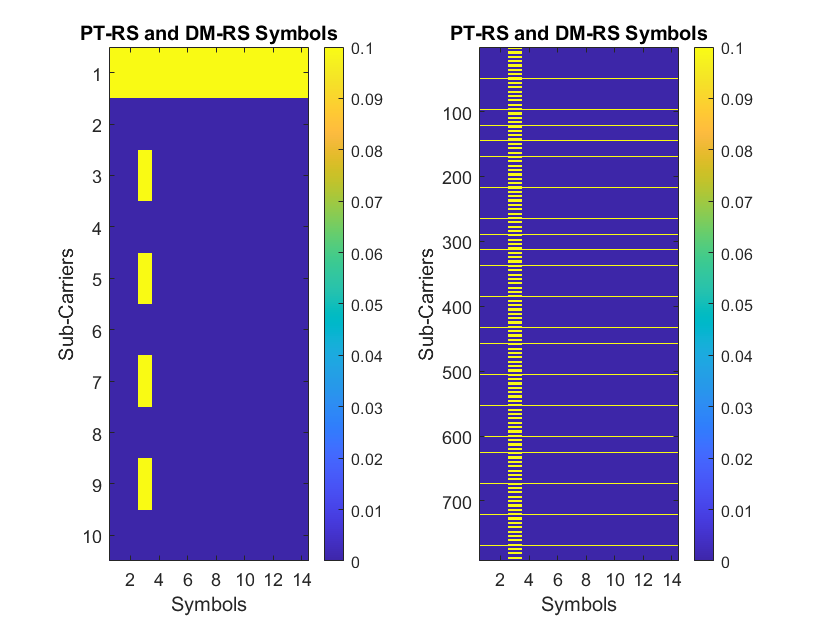

% Number of frames to generate the waveform
simParameters.NumFrames = 2;

% Get the number of slots in the waveform and number of symbols in a slot
numSlots = carrier.SlotsPerFrame*simParameters.NumFrames;
nSlotSymb = carrier.SymbolsPerSlot;

% Initialize the grid for specified number of frames
txGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
txGrid_nodata = txGrid;

% Processing loop
txbits = [];
rng('default')
for slotIdx = 0:numSlots - 1
    % Set slot number
    carrier.NSlot = slotIdx;

    % Get PDSCH indices and structural information
    [pdschInd,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

    % Generate random codeword(s)
    numCW = pdsch.NumCodewords; % Number of codewords
    data = cell(1,numCW);
    for i = 1:numCW
        data{i} = randi([0 1],pdschIndicesInfo.G(i),1);
        txbits = [txbits; data{i}]; %#ok<AGROW>
    end

    % Get modulated symbols
    pdschSym = nrPDSCH(carrier,pdsch,data);

    % Get DM-RS symbols and indices
    dmrsSym = nrPDSCHDMRS       (carrier,pdsch);
    dmrsInd = nrPDSCHDMRSIndices(carrier,pdsch);

    % Get PT-RS symbols and indices
    ptrsSym = nrPDSCHPTRS(carrier,pdsch);
    ptrsInd = nrPDSCHPTRSIndices(carrier,pdsch);

    % Resource element mapping to slot grid
    slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
    slotGrid(dmrsInd)  = dmrsSym;
    slotGrid(ptrsInd)  = ptrsSym;
    slotGrid_nodata = slotGrid;
    slotGrid(pdschInd) = pdschSym;

    % Generate txGrid for all frames by mapping slotGrid at respective
    % locations
    txGrid(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid;
    txGrid_nodata(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid_nodata;
end

% figure(); clf; imagesc(abs(txGrid(1:10,end-14+1:end))); colorbar();

% NOTE that we ca clipping the imagees to show the ~10% fainter signas
% as the range goes from 0 to around 1
CRANGE=[0,0.10];
figure();clf;
subplot(1,2,1); imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
title("PT-RS and DM-RS Symbols"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(slotGrid_nodata(:   ,end-14+1:end)),CRANGE); colorbar();
title("PT-RS and DM-RS Symbols"); xlabel("Symbols"); ylabel("Sub-Carriers")

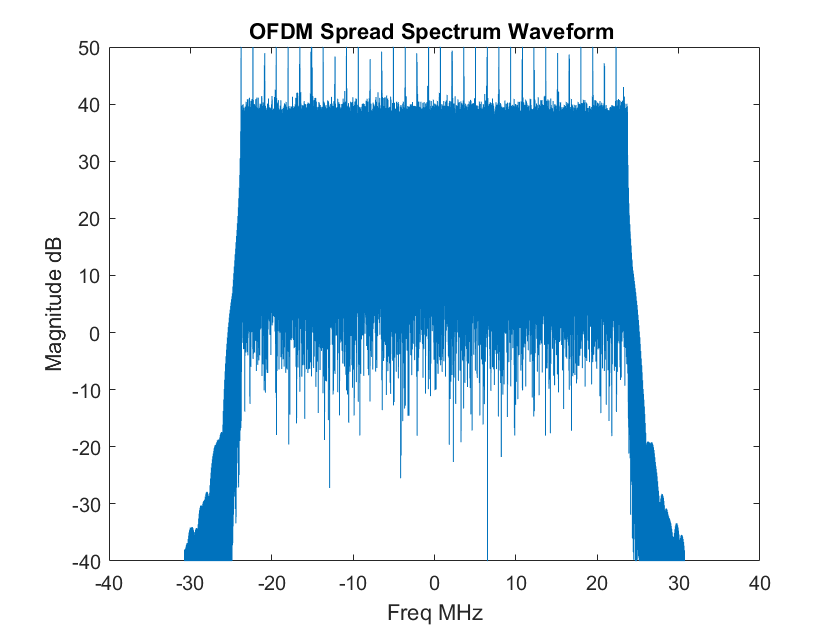




% Perform OFDM modulation
carrier.NSlot = 0; % Reset the slot number to 0 for OFDM modulation
txWaveform        = nrOFDMModulate(carrier,txGrid);
txWaveform_nodata = nrOFDMModulate(carrier,txGrid_nodata);

aux = mag2db(abs(fftshift(fft(txWaveform)))+eps);
x = linspace(-1,1,length(aux))*waveformConfig.SampleRate/2/1e6;
figure();clf;plot(x, aux); ylim([-40,50])
title("OFDM Spread Spectrum Waveform "); xlabel("Freq MHz"); ylabel("Magnitude dB")

## **7. Applying Phase Noise - Ideal Channel**

Now we will apply phase noise to the transmitted waveform. In this first simulation we will not add channel disturbances to the TX signal.

% Apply PN to the frames populated with data
rxWaveform = zeros(size(txWaveform),'like',txWaveform);
for i = 1:size(txWaveform,2)
    rxWaveform(:,i) = pnoise(txWaveform(:,i));
    release(pnoise)
end

% Apply PN to the frames populated DM-RS PT-RS control signals only
rxWaveform_nodata = zeros(size(txWaveform_nodata),'like',txWaveform_nodata);
for i = 1:size(txWaveform_nodata,2)
    rxWaveform_nodata(:,i) = pnoise(txWaveform_nodata(:,i));
    release(pnoise)
end


## **8. Receiver 1 - A Simple Receiver to observe the Intercarrier Interference (ICI)**

Because this first example does not use a propagation channel, the steps of timing synchronization, channel estimation, and equalization are not necessary for this case. The only effect to observe are the ones from the insertion of phase noise.

In this section we will show evidence of ICI due to phase noise. Later we will show the CPE and ways to mitigate the CPE. A full descrition of the topic can be found in the reference (1).

**It is important to differentiate between ISI and ICI.**

Inter-symbol interference (ISI) occurs in the time domain and OFDM use guards (Cyclic Prefixes) to protect from them:

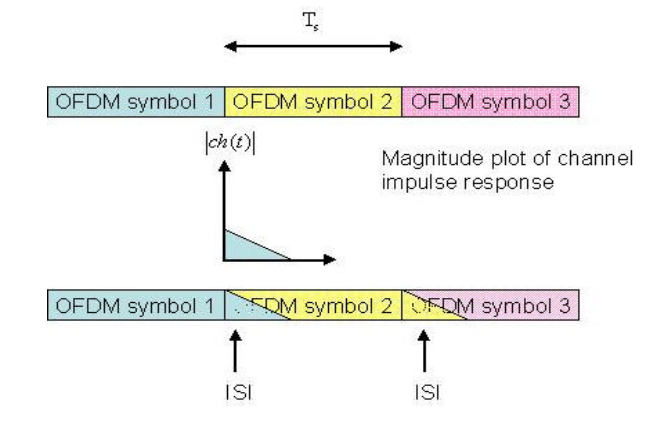

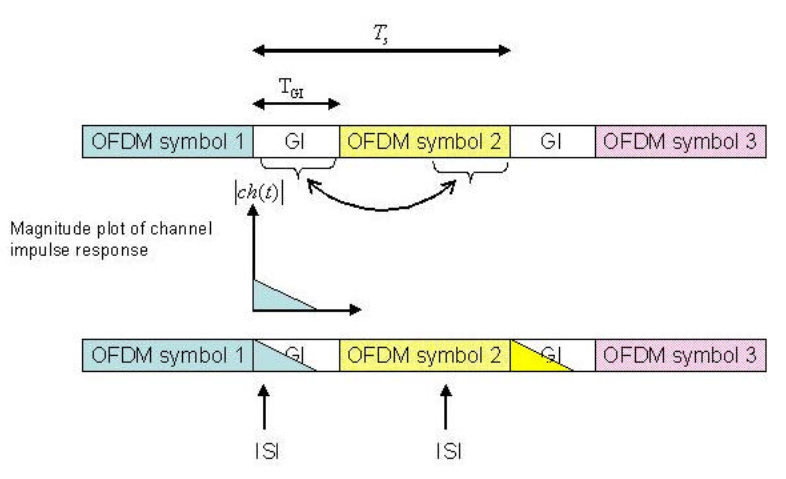

Picture taken from (4), pages 14 and 15

Inter-Carrier Interference (ICI) happens in the frequency domain due to distortions and intermodulations like phase noise and it impairs the orthogonality of the vector space of sinc() functions. The orthogonal property is key to prevent the symbos to interefere in the freq domain:

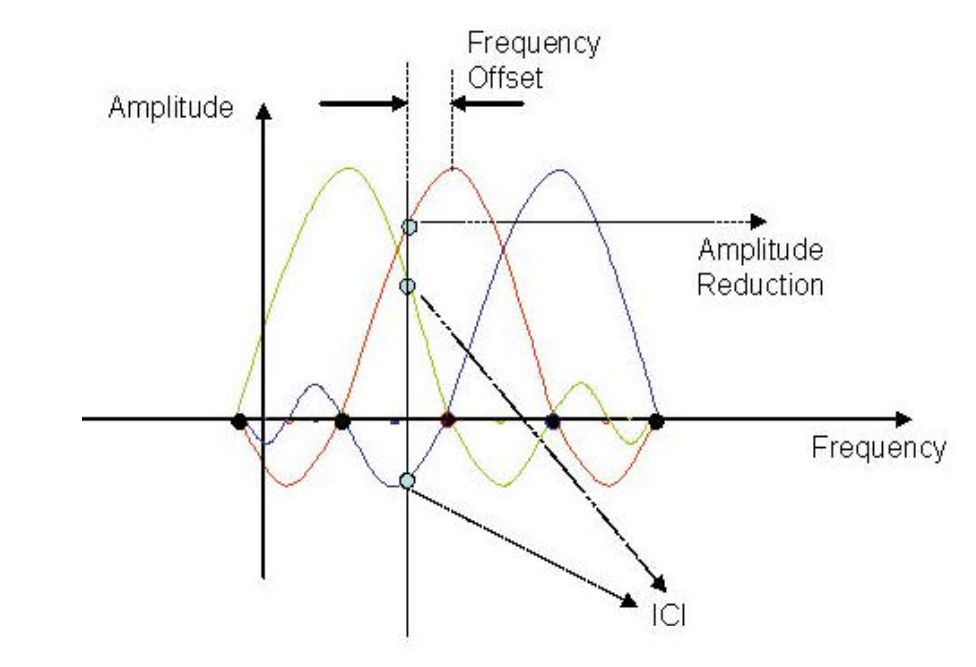

Picture taken from (4), page 25

## 8.1 Below we Demodulate the Signal. Note that the Symbols are Interfering in Frequency.

It is easier to see what is going on when ONLY the DM-RS and PT-RS are present in the slot as shown in the second picture set below.

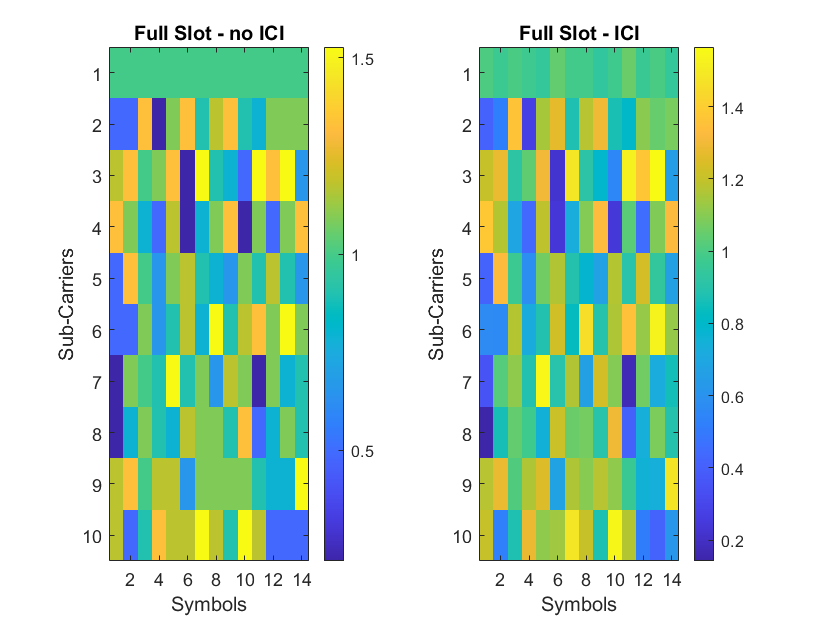


% simParameters.CompensateCPE = 0;
rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
% rxGrid = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
figure(); clf; 
subplot(1,2,1);imagesc(abs(txGrid(1:10,end-14+1:end))); colorbar();
title ("Full Slot - no ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2);imagesc(abs(rxGrid(1:10,end-14+1:end))); colorbar();
title ("Full Slot - ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")

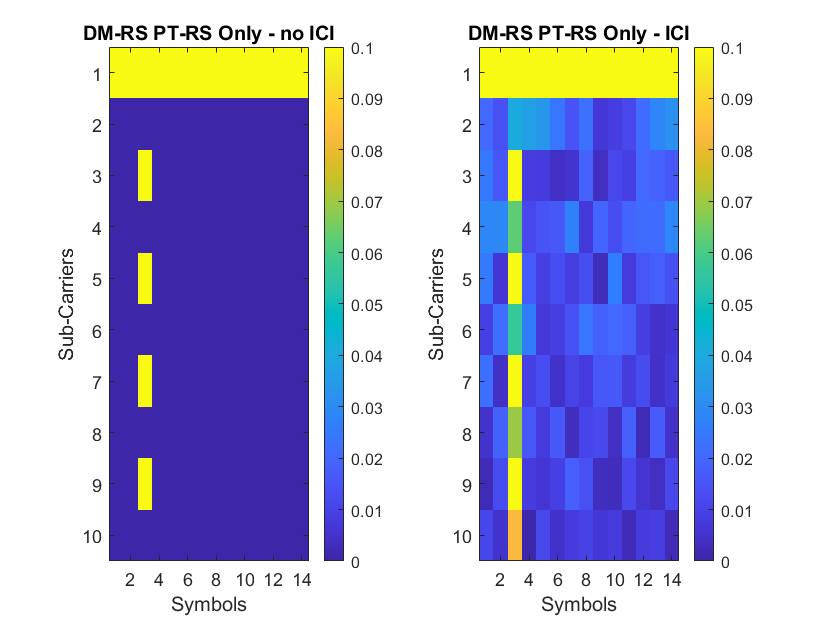

% NOW is much easier to see - we left only the control signals 
% present in the slots

rxGrid_nodata = nrOFDMDemodulate(carrier,rxWaveform_nodata);
% rxGrid_nodata = practicalReceiver(carrier,pdsch,simParameters,rxWaveform_nodata);
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS Only - no ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (1:10,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS Only - ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")

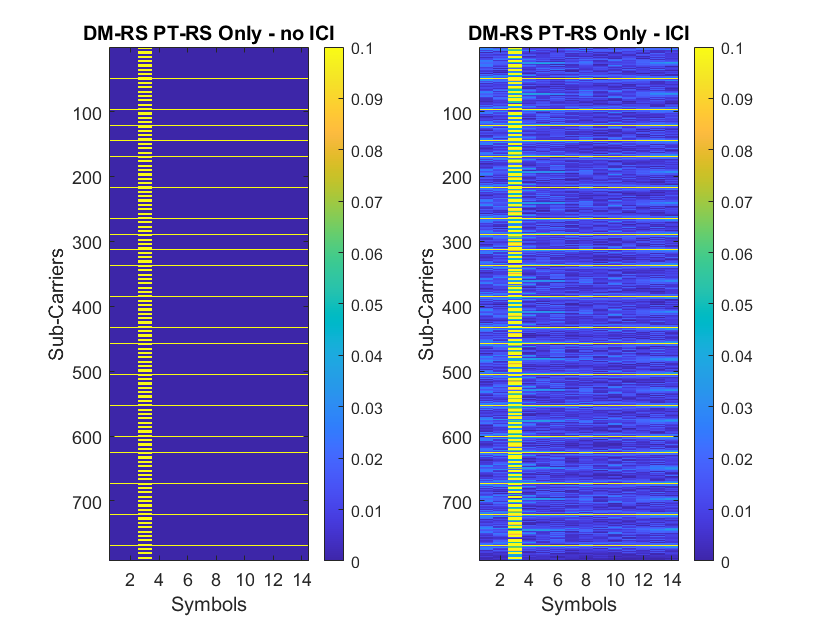

% NOW we show all carriers 

figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(:,end-14+1:end)), CRANGE); colorbar();
title ("DM-RS PT-RS Only - no ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (:,end-14+1:end)), CRANGE); colorbar();
title ("DM-RS PT-RS Only - ICI"); xlabel("Symbols"); ylabel("Sub-Carriers")

## 8.2 A Look into the Leaked Energy due to ICI.

Now we will show in more details what is happening to the energy. We can see that easily by observing the control signals DM-RS and PT-RS and setting the payload ot the slot to zero.

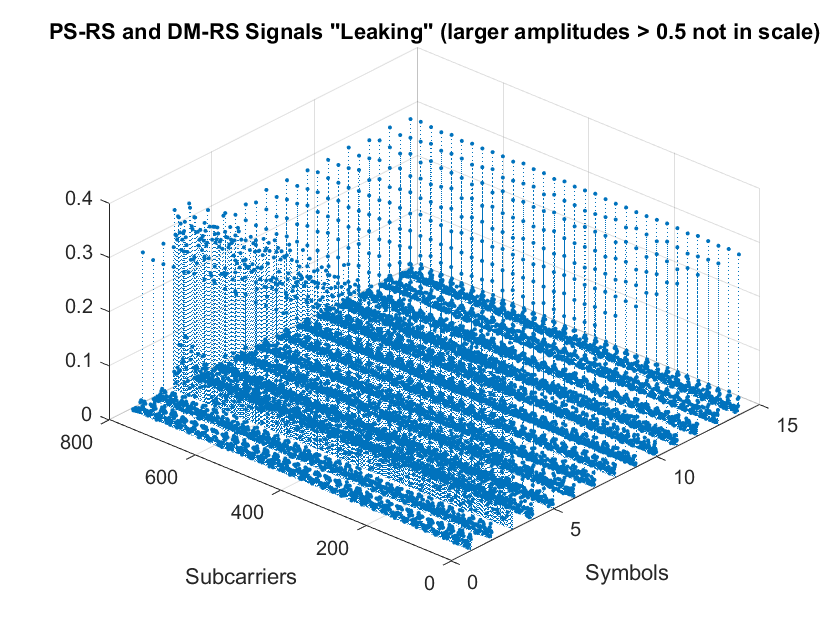


txx = txGrid_nodata(:,end-14+1:end);
rxx = rxGrid_nodata(:,end-14+1:end);

% Collapsing a bit - to better see the leaks
% (larger amplitudes not in scale)
rxx_a = abs(rxx);
rxx_a (rxx_a>0.5) = rxx_a(rxx_a>0.5) - 0.70; 
figure(); clf; stem3 (abs(rxx_a), '.:')

view([-47.929 44.176])
title ("PS-RS and DM-RS Signals ''Leaking'' (amplitudes > 0.5 not in scale)")
xlabel("Symbols"); ylabel("Subcarriers")

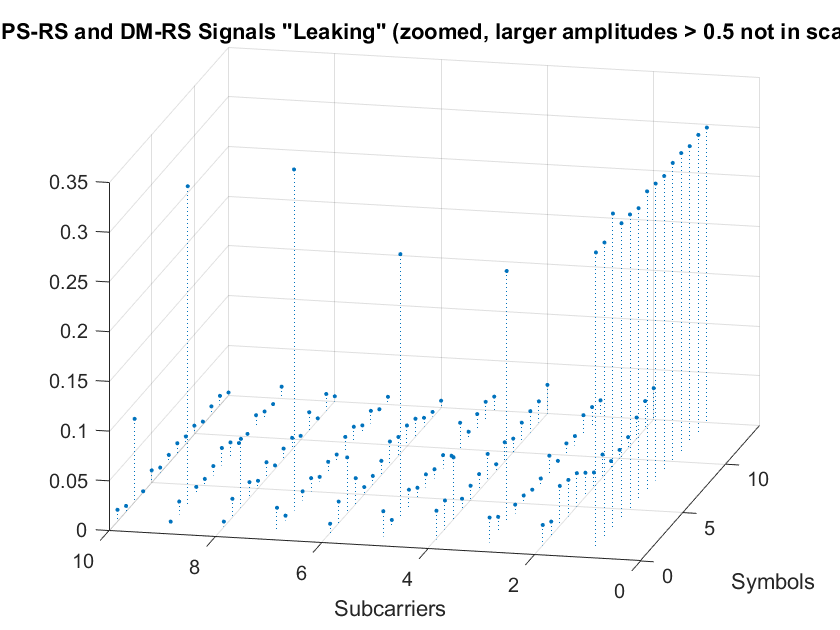

rxx_a = abs(rxx);
rxx_a (rxx_a>0.5) = rxx_a(rxx_a>0.5) - 0.70; 
figure(); clf; stem3 (abs(rxx_a(1:10,1:14)), '.:')

view([-77.329 21.754])
title ("PS-RS and DM-RS Signals ''Leaking'' (zoomed, amplitudes > 0.5 not in scale)")
xlabel("Symbols"); ylabel("Subcarriers")


% view([-57.823 53.351])
leak = abs(abs(rxx) - abs(txx));
sum(rms(txx,1))

ans = 3.3607

sum(rms(rxx,1))

ans = 3.3606

sum(rms(rxx - txx, 1))

ans = 0.2461

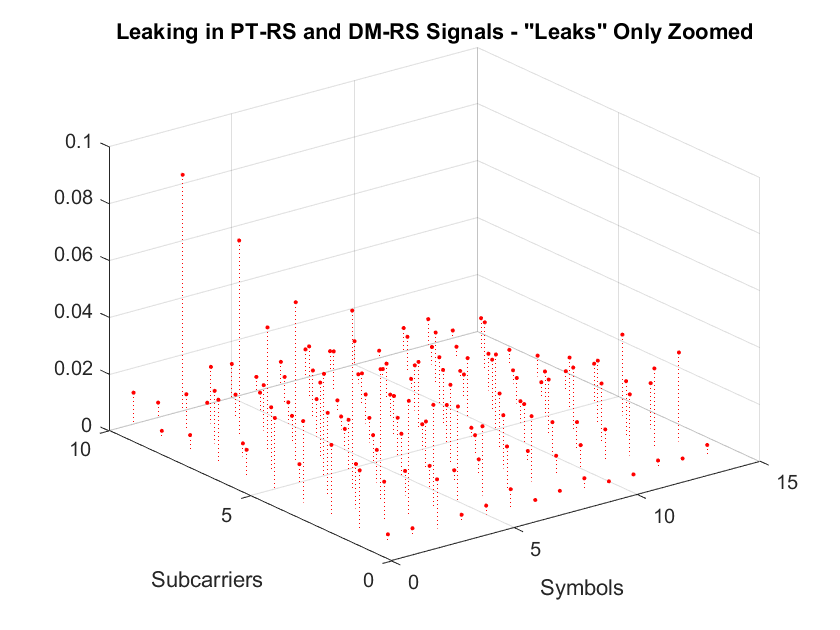

figure(); clf; stem3 (leak(1:10,:), 'r.:')
title ("Leaking in PT-RS and DM-RS Signals - ''Leaks'' Only Zoomed")
xlabel("Symbols"); ylabel("Subcarriers")

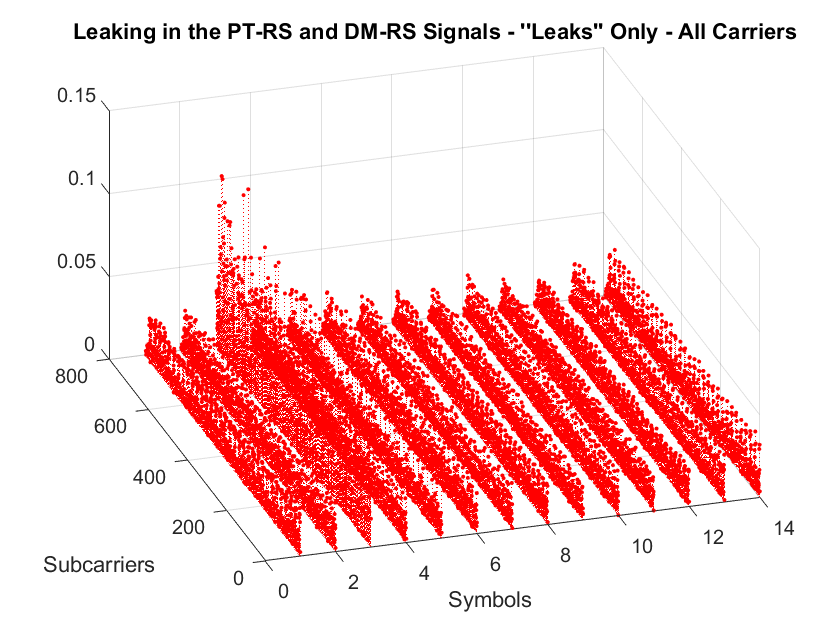

figure(); clf; stem3 (leak(:,:), 'r.:')
view([-17.5000 40.4101])
title ("Leaking in the PT-RS and DM-RS Signals - ''Leaks'' Only - All Carriers")
xlabel("Symbols"); ylabel("Subcarriers")

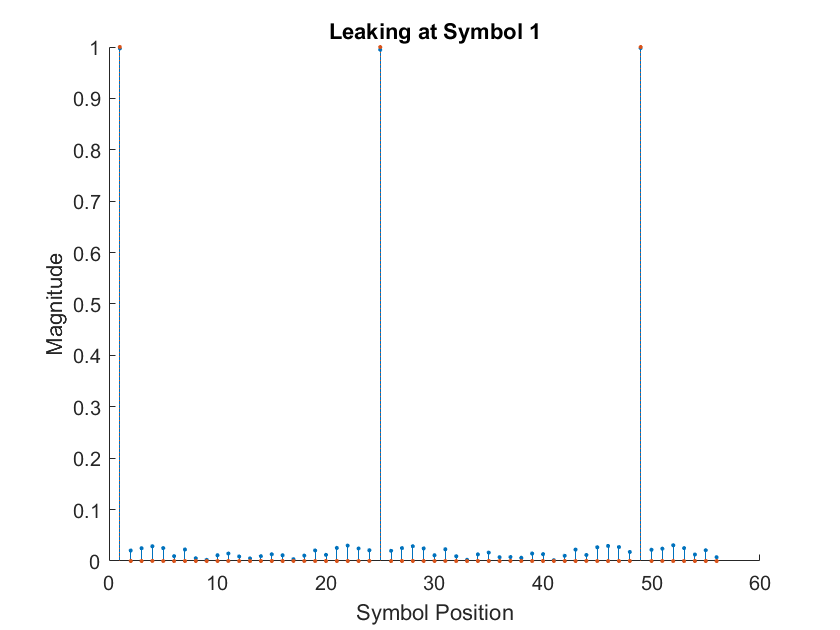


figure(); clf; hold on
stem (abs(rxx(1:14*4,1)), '.' ); 
stem (abs(txx(1:14*4,1)), '.:'); 
% ylim([0,1]/10)
hold off
title ("Leaking at Symbol 1"); ylabel("Magnitude"); xlabel("Symbol Position")

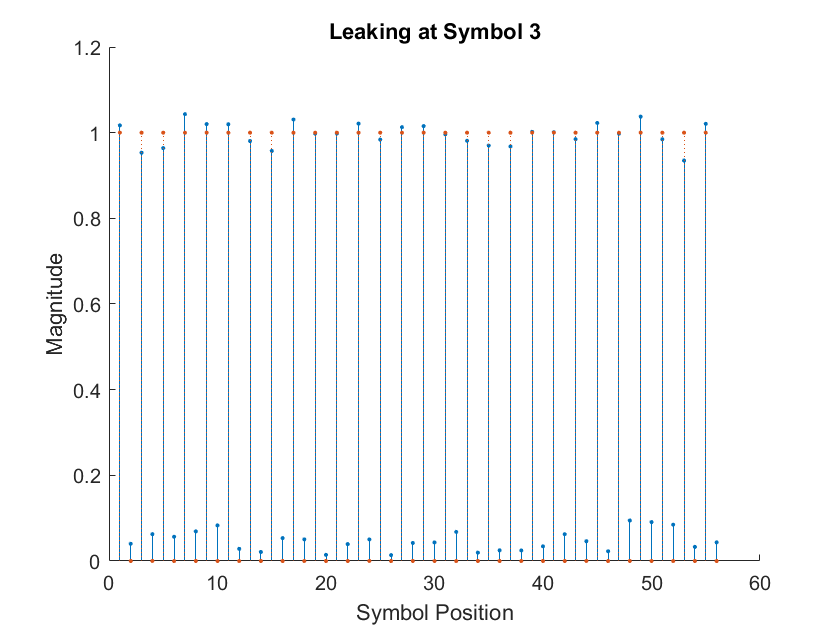


figure(); clf; hold on
stem (abs(rxx(1:14*4,3)), '.' ); 
stem (abs(txx(1:14*4,3)), '.:'); 
title ("Leaking at Symbol 3"); ylabel("Magnitude"); xlabel("Symbol Position")
% ylim([0,1]/10))
hold off

## **9. Receiver 2 - Full Receiver with Proper Equalization and Commom Phase Errror (CPE) Compensation**

Before returning the equalized PDSCH symbols and decoded bits, the receiver performs these steps:

- Timing synchronization

- OFDM demodulation

- Channel estimation

- Equalization

- CPE estimation and correction

- PDSCH decoding

Now we will do the receving using the full receiver chain and compare the EVN, BER with and without CPE compensation.

### **9.1  Without CPE Compensation**

To disable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0.

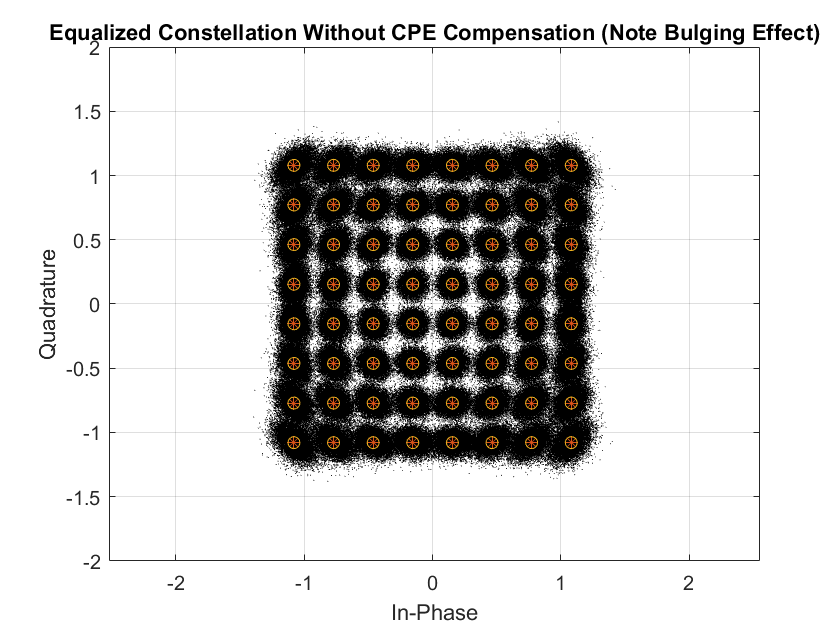

simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = getConstellationPoints(pdsch);
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation Without CPE Compensation (Note Bulging Effect)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); axis equal


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', ...
               'Estimated from reference constellation', ...
               'ReferenceConstellation', refSymbols);

fprintf('RMS EVM (in percent) eq symbols WITHOUT CPE compensation: %f%% \n', ...
         evm(eqSymbols))

RMS EVM (in percent) eq symbols WITHOUT CPE compensation: 8.408854% 



% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate WITHOUT CPE compensation: %f \n',errorRate)

Bit error rate WITHOUT CPE compensation: 0.005004 


### **9.2 With CPE Compensation**

To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

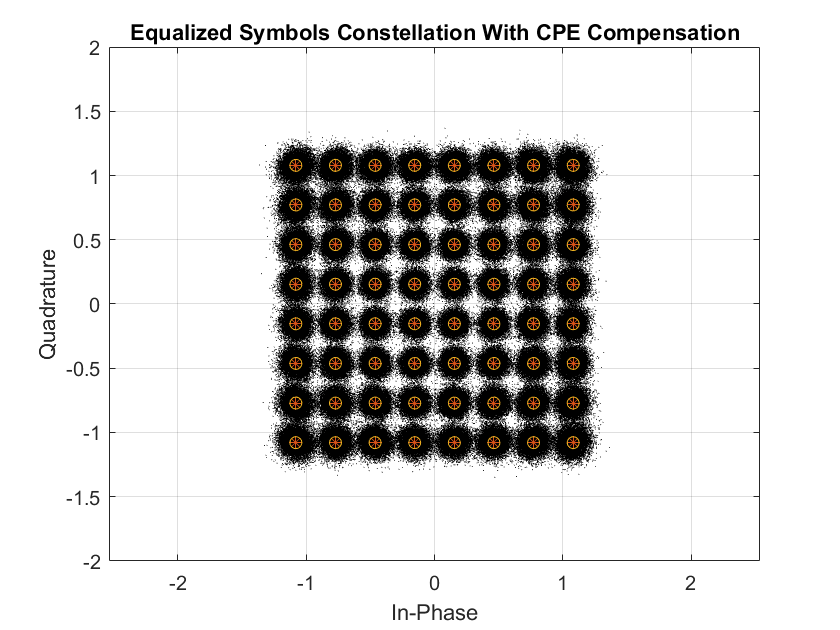

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation With CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); axis equal


% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols WITH CPE compensation: %f%% \n', evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols WITH CPE compensation: 7.440295% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate WITH CPE compensation: %f \n',errorRateCPE)

Bit error rate WITH CPE compensation: 0.001621 


## **10. Simulating  AGWN Fading Channel**

Now we will repeat the Phase Noise simulation in a more realist channel. A fading channel with AGWN.         

### 10.1 Creating the Fading Noisy Channel

% Parmeters for each path
gain  = [-3 -3 -3]';  % path gain in dB
dly   = [0 200e-9 300-9]';  % path delays in seconds
aoaAz = [10, 20, 30]';  % angles of arrival - Azim
aoaEl = [0, 0, 0]';  % angles of arrival - Elev
% Mobile velocity vector in m/s
rxVel = [35,35,0]'; % (vx,vy,vz)

gain = mag2db(db2mag(gain)./ sum(db2mag(gain))); %Normalize gain so max equals mono path case

% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
EsN0Avg = 30;   % Average SNR

% Creates the channel. Reused from our Lab4
fdchan = FDChan(carrier, 'waveformConfig', waveformConfig, ...
                'gain', gain, 'dly', dly, ...
                'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                'rxVel', rxVel, 'Etx', Etx, ...
                'EsN0Avg', EsN0Avg, 'fc', simParameters.Fc)

FDChan->FDChan() Called

fdchan =   FDChan with properties:

     carrierConfig: [1×1 nrCarrierConfig]
    waveformConfig: [1×1 struct]
              gain: [3×1 double]
               dly: [3×1 double]
             aoaAz: [3×1 double]
             aoaEl: [3×1 double]
                fd: [3×1 double]
             rxVel: [3×1 double]
                fc: 6.0000e+10
       gainComplex: [3×1 double]
               Etx: 1
           EsN0Avg: 30
          symStart: [1×56 double]
              Verb: 1


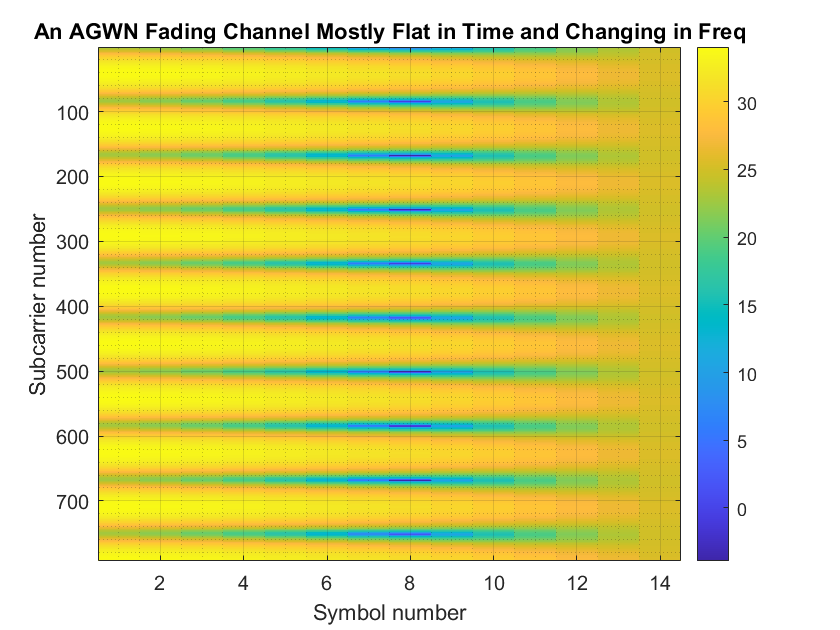


frNum = 0; sfNum = 0; slotNum = 0;
len = waveformConfig.SymbolsPerSlot;
idx = frNum * waveformConfig.SlotsPerSubframe*len + ...
      sfNum * len + 1;
slotGrid = txGrid(:, idx:idx+len-1);
[rxg_fd,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % Does one 792x14 at a time

%
chanSnr = 10*log10(abs(chan).^2/noiseVar);
figure(); clf; imagesc(chanSnr);
grid(gca,'minor'); grid on
colorbar();
xlabel('Symbol number');
ylabel('Subcarrier number');
title("An AGWN Fading Channel Mostly Flat in Time and Changing in Freq")

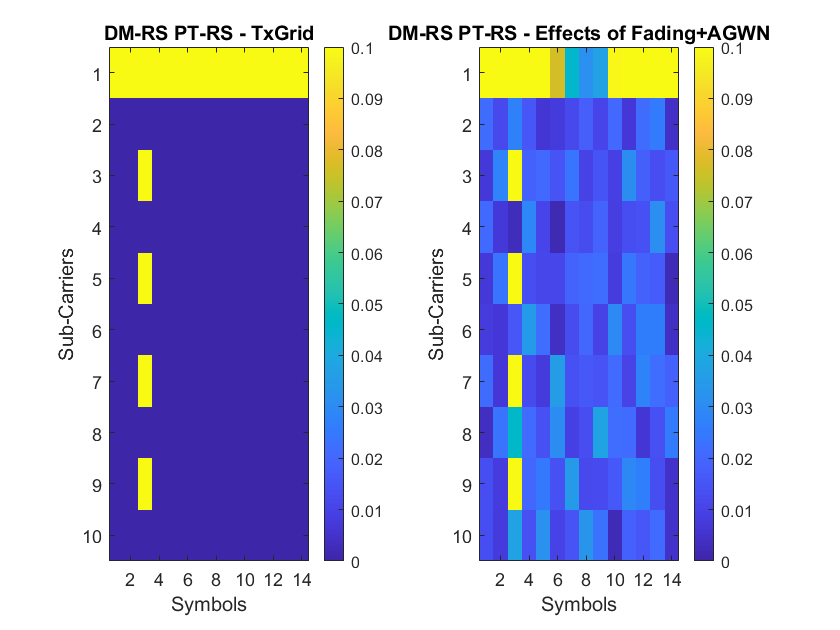


frNum = 0; sfNum = 0; slotNum = 0;
len = waveformConfig.SymbolsPerSlot;
idx = frNum * 10  * waveformConfig.SlotsPerSubframe*len + ...
      sfNum * len + 1;
slotGrid = txGrid_nodata(:, idx:idx+len-1);
[rxg_fd,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % Does one 792x14 at a time

%CRANGE=[0,.5]
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS - TxGrid"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxg_fd         (1:10,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS - Effects of Fading+AGWN"); xlabel("Symbols"); ylabel("Sub-Carriers")

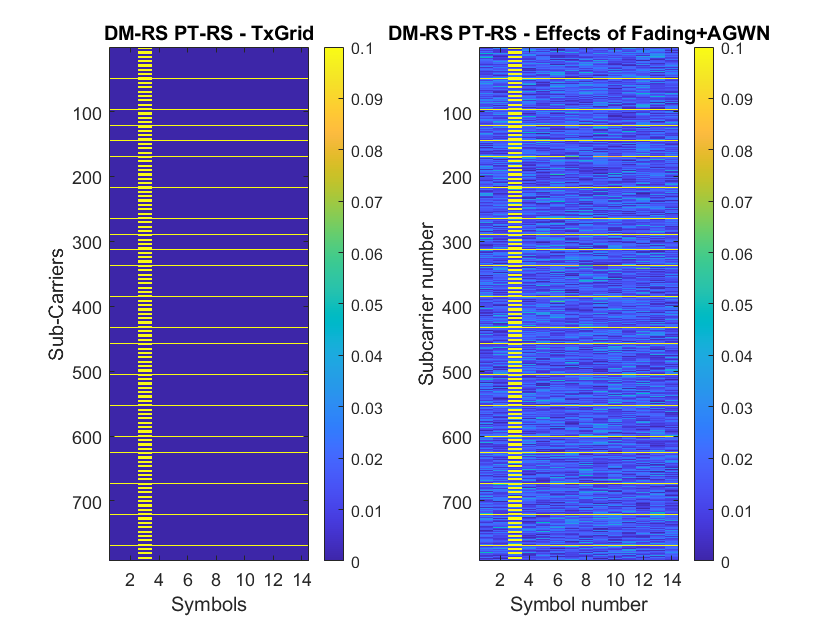


figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(:   ,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS - TxGrid"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxg_fd         (:   ,end-14+1:end)),CRANGE); colorbar();
title ("DM-RS PT-RS - Effects of Fading+AGWN"); xlabel("Symbols"); ylabel("Sub-Carriers")

colorbar();
xlabel('Symbol number');
ylabel('Subcarrier number');

### **10.2  Displaying the Constellation with and without CPE Compensation (No Phase Noise Case)**

We will see that the CPE compensation helps to equaliize the Channel. 

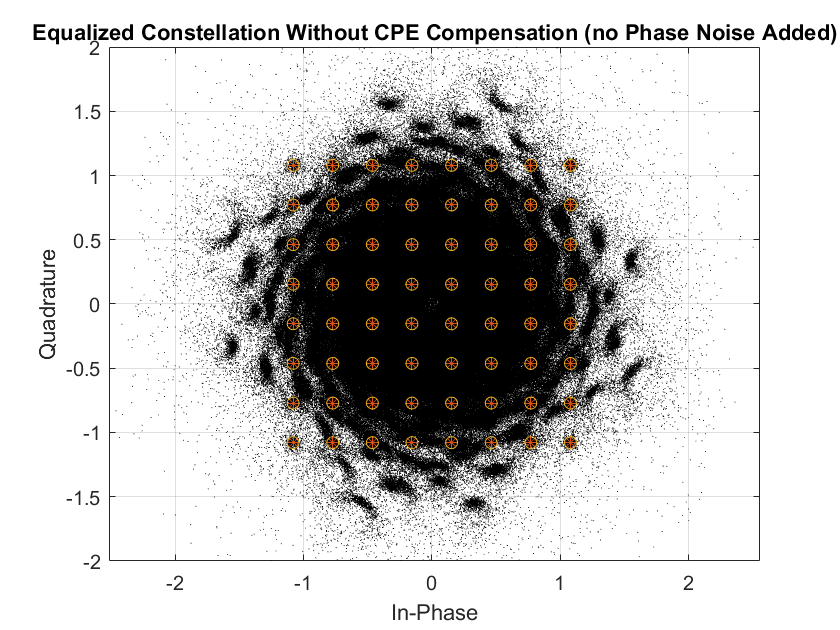

%% Get the number of slots in the waveform and number of symbols in a slot
% numSlots  = carrier.SlotsPerFrame*simParameters.NumFrames;
% nSlotSymb = carrier.SymbolsPerSlot;
% txGrid    = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);

rxFdGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
nsym=1;
for fr = 1:simParameters.NumFrames
   for sub_fr = 1:10 
       for slot = 1:waveformConfig.SlotsPerSubframe
           len = waveformConfig.SymbolsPerSlot;
           %fprintf("fr=%d sub_fr=%2d slot=%d nsym=[%4d,%4d]\n",fr,sub_fr,slot,nsym,nsym+len-1)           
           slotGrid = txGrid(:, nsym:nsym+len-1);
           [rxSlot,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % 792x14 at a time
           rxFdGrid(:, nsym:nsym+len-1) = rxSlot;
           nsym=nsym+waveformConfig.SymbolsPerSlot;
       end
   end
end


rxFDWaveform        = nrOFDMModulate(carrier,rxFdGrid);

simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxFDWaveform);
refSymbols         = getConstellationPoints(pdsch);
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation Without CPE Compensation (no Phase Noise Added)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); axis equal


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', ...
               'Estimated from reference constellation', ...
               'ReferenceConstellation', refSymbols);

fprintf('RMS EVM (in percent) eq symbols WITHOUT CPE compensation: %f%% \n', ...
         evm(eqSymbols))

RMS EVM (in percent) eq symbols WITHOUT CPE compensation: 19.314664% 


% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate WITHOUT CPE compensation: %f \n',errorRate)

Bit error rate WITHOUT CPE compensation: 0.450302 


To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

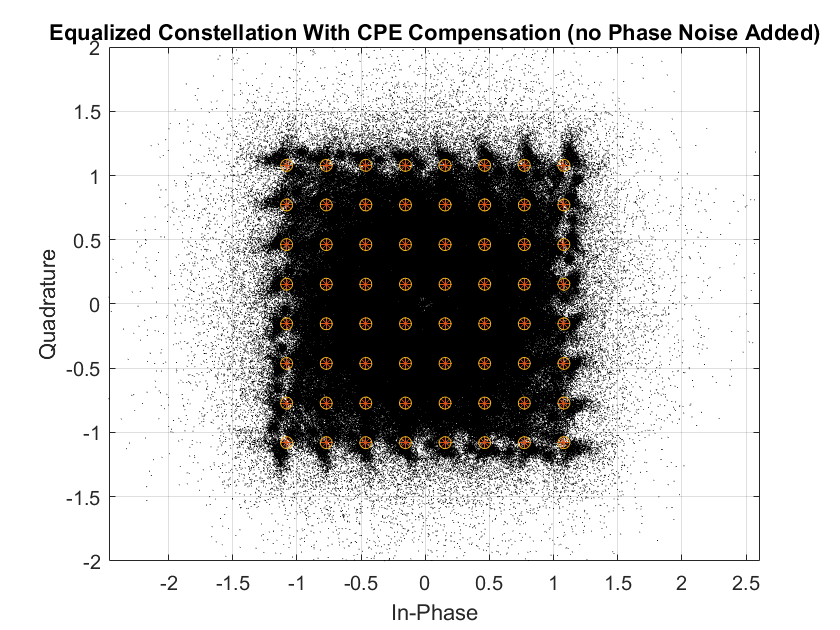

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxFDWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation With CPE Compensation (no Phase Noise Added)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); axis equal


% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols WITH CPE compensation: %f%% \n',evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols WITH CPE compensation: 16.335815% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate WITH CPE compensation: %f \n',errorRateCPE)

Bit error rate WITH CPE compensation: 0.217241 


### **10.3  Diplaying the Constellation with and without CPE Compensation (With Phase Noise Case)**

We will see that the CPE compensation helps to equaliize the Channel here and that there is no significant degradation due to the adding of phase noise.

**Applying phase noise to the transmitted waveform: **now it will be hard to observe the phase noise effect because the noise of channel and the effects of fading will also be present. The example applies the same phase noise to all the layers.

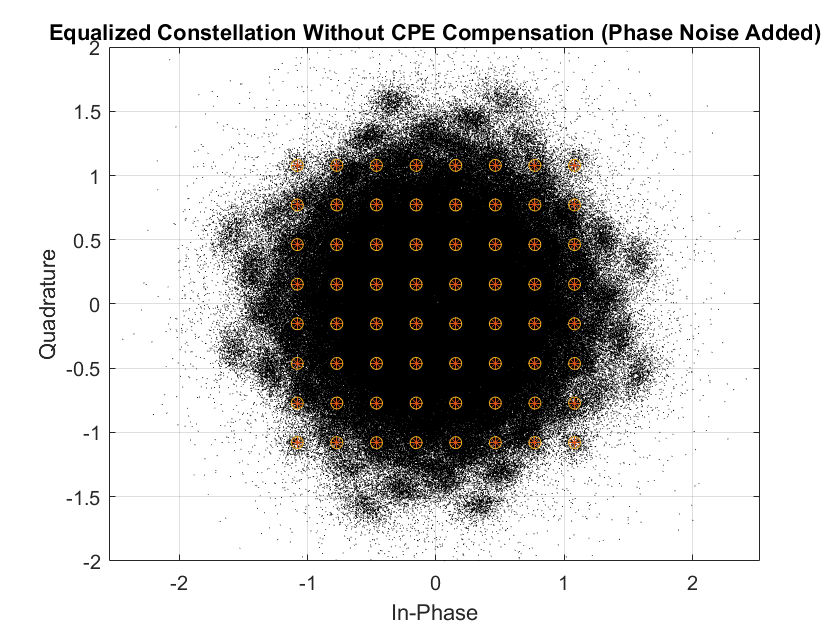

% Apply PN to the frames populated with data
rxWaveform = zeros(size(rxFDWaveform),'like',rxFDWaveform);
for i = 1:size(rxFDWaveform,2)
    rxWaveform(:,i) = pnoise(rxFDWaveform(:,i));
    release(pnoise)
end

simParameters.CompensateCPE = 0;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation Without CPE Compensation (Phase Noise Added)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); 
% NOTE The Lens effect in the picutre below. The Phase Noise Blurs the
% image!
axis equal


% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols WITHOUT CPE compensation: %f%% \n',evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols WITHOUT CPE compensation: 18.861236% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate WITHOUT CPE compensation: %f \n',errorRateCPE)

Bit error rate WITHOUT CPE compensation: 0.450755 


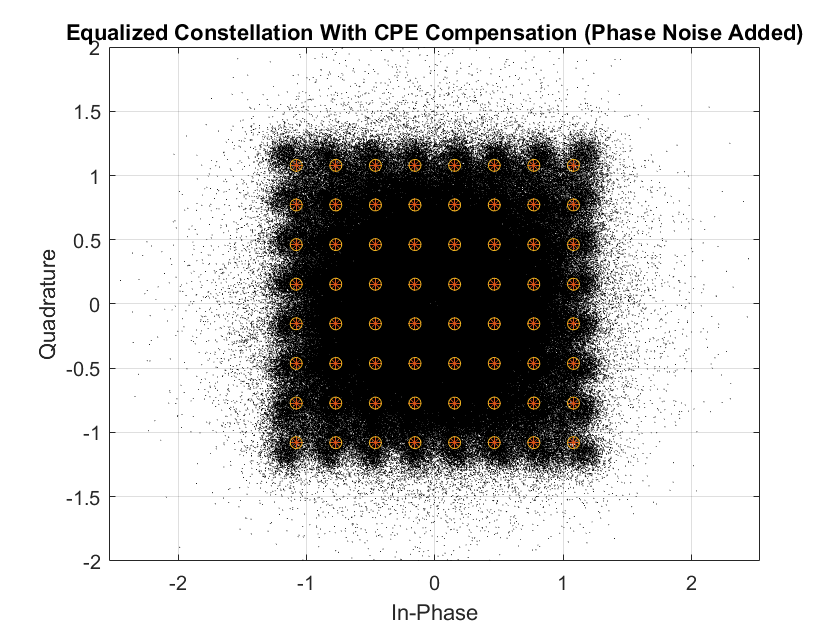


simParameters.CompensateCPE = 1;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = getConstellationPoints(pdsch);
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation With CPE Compensation (Phase Noise Added)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
xlim([-2,2]); ylim([-2,2]); 
% NOTE The Lens effect in the picutre below. The Phase Noise Blurs the
% image!
axis equal


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', ...
               'Estimated from reference constellation', ...
               'ReferenceConstellation', refSymbols);

fprintf('RMS EVM (in percent) eq symbols WITHOUT CPE compensation: %f%% \n', ...
         evm(eqSymbols))

RMS EVM (in percent) eq symbols WITHOUT CPE compensation: 16.132742% 


% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);

% BIT ERROR RATE IMPROVES SIGNIFICANTLY:
fprintf('Bit error rate WITH CPE compensation: %f \n',errorRate)

Bit error rate WITH CPE compensation: 0.224689 


## **11. Conclusions**

In this simulation we saw that PT-RS signals do a good job to equalize the channel and correct CPE and reduces the EVM, helping to compensate in distoritions in the OFDM constellation. Sigificant ICI can be obseved in the case studied (fc = 60 GHz). The phase noise generated by the model was in the order of magniture of the fading channel simulated.

## **12.  For Discussion / Future Work**

The distortion observed in the constellation looks **like a non-linear convex bulge**. The reason for this geometry should be better understood. This work didn't try to compensate for ICI. A suggested extension of this simulation would to be include ICU and also compare other models or phase noise and add thermal noise to the simulated environment. 

## 13. References*:*

(1) Wu, Songping, "Phase noise effects on OFDM : analysis and mitigation" (2004). Dissertations. 645. 

[https://digitalcommons.njit.edu/dissertations/645](https://digitalcommons.njit.edu/dissertations/645)

(2) Mathworks, "NR Phase Noise Modeling and Compensation" 

[https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html](https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html)

(3) [*An Overview of Phase Noise and Jitter*](http://literature.cdn.keysight.com/litweb/pdf/5990-3108EN.pdf) (PDF), Keysight Technologies, May 17, 2001

(4) Erdogan, Ahmet Yasin, "Analysis of the effects of phase noise and frequency offset in orthogonal frequency division multiplexing (OFDM) systems" (2004).

[https://core.ac.uk/download/pdf/36695447.pdf](https://core.ac.uk/download/pdf/36695447.pdf)

(5) Wikipedia [https://en.wikipedia.org/w/index.php?title=Phase_noise](https://en.wikipedia.org/w/index.php?title=Phase_noise)

## **---------------------------------------------------------------------------------------------**

## **---------------------------------------------------------------------------------------------**

## **14. Local Functions**

Most of this code came from ref (2), which some modification.

function [eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,params,rxWaveform)
% Returns equalized modulated symbols after performing the timing
% estimation, OFDM demodulation, channel estimation, MMSE equalization,
% CPE estimation and correction, and PDSCH decoding.

    % Get the current slot number, number of slots, number of symbols
    % per slot, and total number of symbols
    nSlot = carrier.NSlot;
    numSlots = carrier.SlotsPerFrame*params.NumFrames;
    nSlotSymb = carrier.SymbolsPerSlot;
    numTotalSymbols = numSlots*nSlotSymb;

    % Get reference grid with DM-RS symbols
    dmrsSymCell = cell(1,numSlots);
    dmrsIndCell = cell(1,numSlots);
    refGrid = zeros(carrier.NSizeGrid*12,numTotalSymbols,pdsch.NumLayers);
    for NSlot = 0:numSlots-1
        carrier.NSlot = NSlot;
        slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
        dmrsSymCell{NSlot+1} = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndCell{NSlot+1} = nrPDSCHDMRSIndices(carrier,pdsch);
        slotGrid(dmrsIndCell{NSlot+1}) = dmrsSymCell{NSlot+1};
        refGrid(:,NSlot*nSlotSymb+1:(NSlot+1)*(nSlotSymb),:) = slotGrid;
    end

    % Perform timing estimation and correction
    carrier.NSlot = nSlot;
    offset = nrTimingEstimate(carrier,rxWaveform,refGrid);
    waveformSync = rxWaveform(1+offset:end,:);

    % Perform OFDM demodulation on the received data to recreate the
    % resource grid, including padding in the event that practical
    % synchronization results in an incomplete slots being demodulated
    rxGrid = nrOFDMDemodulate(carrier,waveformSync);
    [K,L,R] = size(rxGrid);
    if (L < numTotalSymbols)
        rxGrid = cat(2,rxGrid,zeros(K,numTotalSymbols-L,R));
    end

    % Declare storage variables
    eqSymbols = [];  % equalized symbols for constellation plot
    rxbits = [];

    for NSlot = 0:numSlots-1
        % Extract grid for current slot
        currentGrid = rxGrid(:,NSlot*nSlotSymb+(1:nSlotSymb),:);

        % Get the PDSCH resources
        carrier.NSlot = NSlot;
        dmrsSymbols = dmrsSymCell{NSlot+1};
        dmrsIndices = dmrsIndCell{NSlot+1};
        ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
        ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

        % Channel estimation
        [estChannelGrid,noiseEst] =  ...
           nrChannelEstimate(currentGrid,dmrsIndices,dmrsSymbols,...
           "CDMLengths",pdsch.DMRS.CDMLengths);

        % Get PDSCH resource elements from the received grid
        [pdschRx,pdschHest] = ...
           nrExtractResources(pdschIndices,currentGrid,estChannelGrid);

        % Equalization
        pdschEq = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Common phase error (CPE) estimation and correction
        if params.CompensateCPE
            % Initialize temporary grid to store equalized symbols
            tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);

            % Extract PT-RS symbols from received grid and estimated
            % channel grid
            [ptrsRx,ptrsHest,~,~,~,ptrsLayerIndices] = ...
                nrExtractResources(ptrsIndices,currentGrid,estChannelGrid,tempGrid);

            % Equalize PT-RS symbols and map them to tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimate the residual channel at the PT-RS locations in
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);

            % Sum estimates across subcarriers, receive antennas, and
            % layers. Then, get the CPE by taking the angle of the
            % resultant sum
            cpe = angle(sum(cpe,[1 3 4]));

            % Map the equalized PDSCH symbols to tempGrid
            tempGrid(pdschIndices) = pdschEq;

            % Correct CPE in each OFDM symbol within the range of reference
            % PT-RS OFDM symbols
            if numel(pdschIndicesInfo.PTRSSymbolSet) > 0
                symLoc = pdschIndicesInfo.PTRSSymbolSet(1) ...
                        +1:pdschIndicesInfo.PTRSSymbolSet(end) +1;
                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
            end

            % Extract PDSCH symbols
            pdschEq = tempGrid(pdschIndices);
        end

        % Store the equalized symbols and output them for all the slots
        eqSymbols = [eqSymbols; pdschEq]; %#ok<AGROW>

        % Decode the PDSCH symbols and get the hard bits
        eqbits = nrPDSCHDecode(carrier,pdsch,pdschEq);
        for i = 1:numel(eqbits)
            rxbits = [rxbits; double(eqbits{i}<0)]; %#ok<AGROW>
        end

    end

end

function sym = getConstellationPoints(pdsch)
%getConstellationPoints Constellation points
%   SYM = getConstellationPoints(PDSCH) returns the constellation points
%   SYM based on modulation schemes provided in PDSCH configuration object.
    sym = [];
    modulation = string(pdsch.Modulation);  % Convert modulation scheme to string type
    ncw = pdsch.NumCodewords;               % Number of codewords
    if ncw == 2 && (numel(modulation) == 1)
        modulation(end+1) = modulation(1);
    end
    % Get the constellation points
    for cwIndex = 1:ncw
     qm = strcmpi(modulation(cwIndex),{'QPSK','16QAM','64QAM','256QAM'})*[2 4 6 8]';
     sym = [sym; nrSymbolModulate(reshape(de2bi(0:2^qm-1,qm,'left-msb')',[],1), ...
            modulation(cwIndex))]; %#ok<AGROW>
    end

end

function phase_noise_psd = PN_Model2Use(f, fc, model)
%   Phase noise characteristic with pole-zero model
%   PSD = hPhaseNoisePoleZeroModel(F,Fc,model) generates the phase noise
%   characteristic PSD in dBc/Hz for the frequency offset values specified
%   by vector F for the carrier frequency Fc. 
%   
%   Models:  
%   
%   'A' :::  parameters used are obtained from the response of a practical oscillator 
%   operated at 30 GHz, as per 3Gpp model R1-163984. Similarly, when MODEL is set to 
% 
%   'B' :::  parameters used are obtained from the response of a practical
%   oscillator operated at 60 GHz, as also specified in 2Gpp doc R1-163984. 
%   
%   'C' ::: the parameters used are obtained from the response of a
%   practical oscillator operated at 29.55 GHz, as specified in TR 38.803.
%
%   More info on https://www.3gpp.org/ftp/tsg_ran/WG1_RL1/TSGR1_85/Docs/R1-163984.zip
%   https://portal.3gpp.org/desktopmodules/Specifications/SpecificationDetails.aspx?specificationId=3069
%   Based on 
%   https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html
%
    fcBase = 30e9;
    fz     = [1.8 2.2 40]*1e6;
    fp     = [0.1 0.2 8]*1e6;
    alphaz = [2 2 2];
    alphap = [2 2 2];
    psd0   = -79.4;  
    
    % Pole/zeros and psd0
    switch model
            case 'A'
                % Parameter set A (R1-163984)
                fcBase = 30e9;
                fz     = [1.8 2.2 40]*1e6;
                fp     = [0.1 0.2 8]*1e6;
                alphaz = [2 2 2];
                alphap = [2 2 2];
                psd0   = -79.4;
            case 'B'
                % Parameter set B (R1-163984)
                fcBase = 60e9;
                fz     = [0.02 6 10]*1e6;
                fp     = [0.005 0.4 0.6]*1e6;
                alphaz = [2 2 2];
                alphap = [2 2 2];
                psd0   = -70;
            case 'C'
                % Parameter set C (TR 38.803)
                fcBase = 29.55e9;
                fz     = [3e3 550e3 280e6];
                fp     = [1 1.6e6 30e6];
                alphaz = [2.37 2.7 2.53];
                alphap = [3.3 3.3 1];
                psd0   = 32;
    end

    % Compute numerator
    num = ones(size(f));
    for idx = 1:numel(fz)
        num = num.*(1 + (f./fz(idx)).^alphaz(idx));
    end

    % Compute denominator
    den = ones(size(f));
    for idx = 1:numel(fp)
        den = den.*(1 + (f./fp(idx)).^alphap(idx));
    end

    % Compute psd
    phase_noise_psd = 10*log10(num./den) + psd0 + 20*log10(fc/fcBase);

end
